# Closed-box loudspeaker coupled to:

- an electrical resonator                 (System A)

- a mechanical resonator               (System B)

- an electromechanical resonator  (System C)

## Parameters

% Speaker (Visaton AL-170)
S_d = 133E-4;    % Effective piston area [m^2]
M  = 13E-3;      % Moving mass [kg]
R_m = 0.6;       % Mechanical resitance [N.s/m]
C_m = 594.85E-6; % Mechanical complicance due to surround suspension and spider [m/N]
C_ab = 10;       % Compliance of enclosure due to back pressure [N/m^4]
Bl = 6.9;        % Force factor [N/A]
L_e = 0.9E-3;    % Voice coil inductance [H]
R_e = 5.6;       % DC coil resistance [Ohm]

% Electrical resonator Shunt network
L_l = 3.46E-3;   % [H] 
R_l = -1.84;     % [Ohm] negative?????
C_l = 706.74E-6; % Resonatore capacitance 

% Freq range
freq = 16:0.1:1000;
omega = 2*pi*freq;

## System A

%Specific acoustic impedance Z_s_A

Re_Zs_A = R_m/S_d + ((Bl)^2*(R_e + R_l))./(S_d*((R_e+R_l)^2 + (omega*(L_e +L_l) - 1./(omega*C_l)).^2));
Im_Zs_A = (omega*M - (1/C_m + S_d^2/C_ab)./omega)./S_d - ((Bl)^2*(omega*(L_e + L_l) - 1./(omega*C_l)))/(S_d*((R_e+R_l)^2+(omega*(L_e+L_l)-1./(omega*C_l)).^2));

Mg_Zs_A = sqrt(Re_Zs_A.^2 + Im_Zs_A.^2); %Magnitude
Ph_Zs_A = atan(Im_Zs_A./Re_Zs_A); %Phase


## Plot

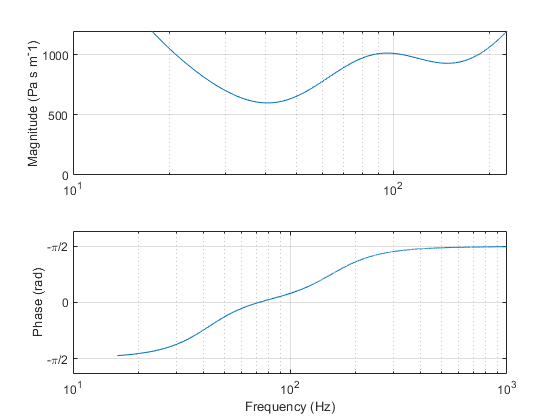



close all

figure(1)
subplot(2,1,1);
semilogx(freq,Re_Zs_A)
ylabel("Real Part (Pa s m^-1)")
ylim([0 1200])
grid on
set(gca,'XLabel',[])

subplot(2,1,2); 
semilogx(freq,Im_Zs_A)
ylabel("Imaginary Part (Pa s m^-1)")
xlabel("Frequency (Hz)")
grid on

figure(2)
subplot(2,1,1);
semilogx(freq,Mg_Zs_A)
ylabel("Magnitude (Pa s m^-1)")
ylim([0 1200])
grid on
set(gca,'XLabel',[])

subplot(2,1,2); 
semilogx(freq,Ph_Zs_A)
ylabel("Phase (rad)")
yticks([-pi/2 0 pi/2])
yticklabels({'-\pi/2','0','-\pi/2'})
xlabel("Frequency (Hz)")
grid on